clear
%%%%%%%%%%%
c_C = 0;  %ド　　 C
c_Cs= 1;  %ド＃　 C#
c_D = 2;  %レ　　 D
c_Ds= 3;  %レ＃　 D#
c_E = 4;  %ミ　　 E
c_F = 5;  %ファ　 F
c_Fs= 6;  %ファ＃ F#
c_G = 7;  %ソ　　 G
c_Gs= 8;  %ソ＃　 G#
c_A = 9;  %ラ　　 A
c_As=10;  %ラ＃　 A#
c_B =11;  %シ　　 B
rest=-1;
%%%%%%%%%%%

%各音符において生成する

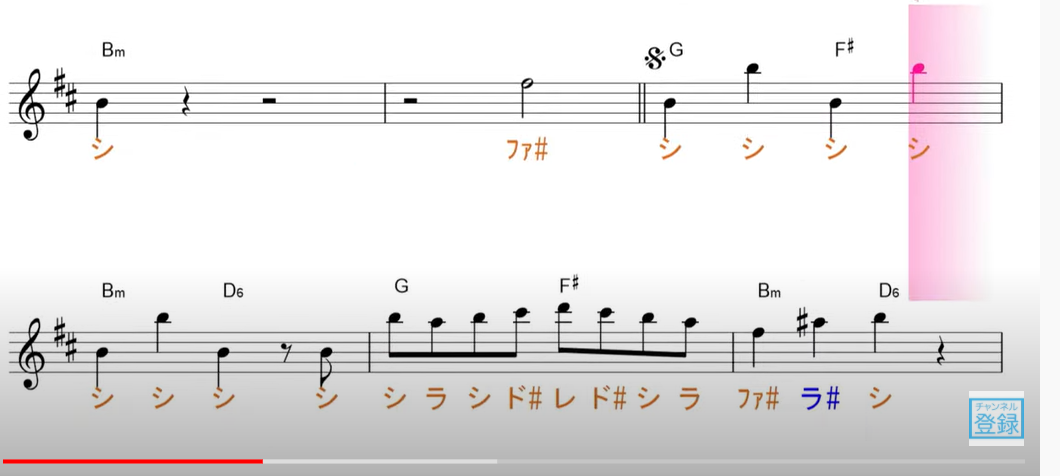


sym = 1;%note:1,rest:0
eta_c = c_C; %Cromatic scale note number
eta_o = 3; %octave number

N_bar = 4;%小節の数

N_sym1 = 4;%小節内の音(音符，休符)の数
N_sym2 = 5;%小節内の音(音符，休符)の数
N_sym3 = 8;%小節内の音(音符，休符)の数
N_sym4 = 4;%小節内の音(音符，休符)の数
BAR1(N_sym1,1) = zeros();
BAR2(N_sym2,1) = zeros();
BAR3(N_sym3,1) = zeros();
BAR4(N_sym4,1) = zeros();
BAR = cat(1,BAR1,BAR2,BAR3,BAR4);
N_sym = numel(BAR); %音の数

SYM_eta_c(N_sym,1) = zeros();%音のCromatic scale note number配列
eta_c1 = [c_B ,c_B ,c_B ,c_B ]';
eta_c2 = [c_B ,c_B ,c_B ,rest,c_B ]';
eta_c3 = [c_B ,c_A ,c_B ,c_Cs,c_D ,c_Cs,c_B ,c_A ]';
eta_c4 = [c_Fs,c_A ,c_B ,rest]';
SYM_eta_c = cat(1,eta_c1,eta_c2,eta_c3,eta_c4);

SYM_eta_o(N_sym,1) = zeros();%音のオクターブ配列
eta_o1 = [3,4,3,4]';
eta_o2 = [3,4,3,rest,4]';
eta_o3 = [4,4,4,4,4,4,4,4]';
eta_o4 = [4,4,4,rest]';
SYM_eta_o = cat(1,eta_o1,eta_o2,eta_o3,eta_o4);

SYM_sym(N_sym,1) = zeros();%符号配列
for k = 1:1:N_sym    
   if SYM_eta_c(k,1) == rest
       SYM_sym(k,1) = 0;
   else       
       SYM_sym(k,1) = 1;
   end
end

SYM_f_H(N_sym,1) = zeros();%音の周波数配列
SYM_rot(N_sym,1) = zeros();%CW/CCW回転方向切替配列
n_rest = 0;%休符の数のカウント
for k = 1:1:N_sym
    %音の周波数配列
    SYM_f_H(k,1) = MusicFunction_f_H(SYM_sym(k,1),SYM_eta_c(k,1),SYM_eta_o(k,1));    
    
    %CW/CCW回転方向切替配列
    if SYM_f_H(k,1) == 0
        n_rest = 1 + n_rest;
    else
    end    
    if rem(k+n_rest,2) == 1     
        SYM_rot(k,1) = 1;    
    else
        SYM_rot(k,1) = 0; 
    end
end

SYM_eta_c

SYM_eta_c =     11
    11
    11
    11
    11
    11
    11
    -1
    11
    11


SYM_eta_o

SYM_eta_o =      3
     4
     3
     4
     3
     4
     3
    -1
     4
     4


SYM_f_H

SYM_f_H =   493.8833
  987.7666
  493.8833
  987.7666
  493.8833
  987.7666
  493.8833
         0
  987.7666
  987.7666


SYM_rot

SYM_rot =      1
     0
     1
     0
     1
     0
     1
     1
     0
     1



%%%%%%%%%%%%%%%%%%%%%
b_t = 4;  %beat :ビート [-]
f_t = 178;%tempo:テンポ [bpm]
SYM_d_note(N_sym,1) = zeros();%分割数配列
d_note1 = [4,4,4,4]';
d_note2 = [4,4,4,8,8]';
d_note3 = [8,8,8,8,8,8,8,8]';
d_note4 = [4,4,4,4]';
SYM_d_note = cat(1,d_note1,d_note2,d_note3,d_note4);

SYM_t_s(N_sym,1) =zeros();
for k = 1:1:N_sym
    %音の時間配列[s]
    %ｋ番目の音の時間
    SYM_t_s(k,1) = MusicFunction_t_s(b_t,f_t,SYM_d_note(k,1));
end
SYM_t_s

SYM_t_s =     0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.3371
    0.1685
    0.1685
    0.1685




%%%%%%%%%%%%%%%%%%%%%
f_L = 50;%起動周波数[Hz]
R_a = 50e-6;%加速レート[s/Hz]
R_d = 50e-6;%減速レート[s/Hz]

SYM_N(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音に必要なパルス数
    SYM_N(k,1) = MusicFunction_N(SYM_sym(k,1),SYM_t_s(k,1),SYM_f_H(k,1),f_L,R_a,R_d);
end
SYM_N

SYM_N =    156
   288
   156
   288
   156
   288
   156
     0
   121
   121



%%%%%%%%%%%%%%%%%%%%%
%判別式
%%もし三角駆動となった場合は，望む音を出すことが出来ない．
SYM_D_eq(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音に必要なパルス数
    SYM_D_eq(k,1) = function_D_eq(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1));
end


D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

休符

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

D_eq > 0 となるため 台形駆動

休符


SYM_D_eq

SYM_D_eq = 	1.0e+03 *

    1.2732
    1.4128
    1.2732
    1.4128
    1.2732
    1.4128
    1.2732
         0
    0.5687
    0.5687


%%%%%%%%%%%%%%%%%%%%%
SYM_t_H(N_sym,1) =zeros();
SYM_t_max(N_sym,1) =zeros();
SYM_t_a(N_sym,1) =zeros();
SYM_t_b(N_sym,1) =zeros();
SYM_t_c(N_sym,1) =zeros();
SYM_t_sum(N_sym,1) =zeros();
SYM_N_a(N_sym,1) =zeros();
SYM_N_b(N_sym,1) =zeros();
SYM_N_c(N_sym,1) =zeros();
for k = 1:1:N_sym
    %ｋ番目の音の各種情報
    [SYM_t_H(k,1),...
        SYM_t_max(k,1),...
        SYM_t_a(k,1),...
        SYM_t_b(k,1),...
        SYM_t_c(k,1),...
        SYM_t_sum(k,1),...
        SYM_N_a(k,1),...
        SYM_N_b(k,1),...
        SYM_N_c(k,1)] = ...
        function_drive_info(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1));
    if SYM_sym(k,1) == 0
        SYM_t_b(k,1) = SYM_t_s(k,1);
        SYM_t_sum(k,1) = SYM_t_s(k,1);
    end
end

仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.044388 [s]
Nを無視し，三角駆動した場合の総時間 =0.17171 [s]
加速に必要な時間 =0.022194 [s]
等速に必要な時間 =0.29157 [s]
減速に必要な時間 =0.022194 [s]
台形駆動にかかる時間 =0.33596 [s]
加速に必要なパルス数 =6 [-]
等速に必要なパルス数 =144 [-]
減速に必要なパルス数 =6 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.093777 [s]
Nを無視し，三角駆動した場合の総時間 =0.23505 [s]
加速に必要な時間 =0.046888 [s]
等速に必要な時間 =0.24297 [s]
減速に必要な時間 =0.046888 [s]
台形駆動にかかる時間 =0.33675 [s]
加速に必要なパルス数 =24 [-]
等速に必要なパルス数 =240 [-]
減速に必要なパルス数 =24 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.044388 [s]
Nを無視し，三角駆動した場合の総時間 =0.17171 [s]
加速に必要な時間 =0.022194 [s]
等速に必要な時間 =0.29157 [s]
減速に必要な時間 =0.022194 [s]
台形駆動にかかる時間 =0.33596 [s]
加速に必要なパルス数 =6 [-]
等速に必要なパルス数 =144 [-]
減速に必要なパルス数 =6 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.093777 [s]
Nを無視し，三角駆動した場合の総時間 =0.23505 [s]
加速に必要な時間 =0.046888 [s]
等速に必要な時間 =0.24297 [s]
減速に必要な時間 =0.046888 [s]
台形駆動にかかる時間 =0.33675 [s]
加速に必要なパルス数 =24 [-]
等速に必要なパルス数 =240 [-]
減速に必要なパルス数 =24 [-]
仮にf_max=f_Hとなるときの総時間(=t_a+t_d) = 0.044388 [s]
Nを無視し，三角駆動した場合の総時間 =0.17171 [s]
加速に必要な時間 =0.02


% SYM_t_H
% SYM_t_max
% SYM_t_a
SYM_t_b

SYM_t_b =     0.2916
    0.2430
    0.2916
    0.2430
    0.2916
    0.2430
    0.2916
    0.1685
    0.0739
    0.0739


% SYM_t_c
SYM_t_sum

SYM_t_sum =     0.3360
    0.3367
    0.3360
    0.3367
    0.3360
    0.3367
    0.3360
    0.1685
    0.1677
    0.1677


% SYM_N_a
% SYM_N_b
% SYM_N_c
% 

%%%%%%%%%%%%%%%%%%%%%%
theta_s_deg = 0.72;
%理想的な励磁タイミング行列を作成

%k列目がk番目の音価の理想的な励磁タイミング配列となっている
T_M(max(SYM_N),N_sym)=zeros();
THETA_r_deg(max(SYM_N),N_sym) = zeros();
    for k = 1:1:N_sym
        if SYM_N(k,1) ~= 0%休符の時のT_Mを飛ばすためのfor文
            [T_M(1:SYM_N(k,1),k),THETA_r_deg(1:SYM_N(k,1),k)]=...
            function_T_M(SYM_f_H(k,1),f_L,R_a,R_d,SYM_N(k,1),theta_s_deg);        
        else            
        end
    end


D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動
台形駆動のタイミング配列を作製
加速時のT_Mを作成
等速時のT_Mを作成
減速時のT_Mを作成

D_eq > 0 となるため 台形駆動

T_M

T_M =     0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078         0    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078         0
    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119         0    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119    0.0119         0
    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150         0    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150         0
    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177         0    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177    0.0177         0
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200         0    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200

    
%%%%%
%パルスを生成
T_s = 1e-6;
SYM_nu(N_sym,1) = zeros();%k番目の符号に必要なnu
    for k = 1:1:N_sym
        SYM_nu(k,1) = round(SYM_t_sum(k,1)/T_s);%一応任意に選ぶことが可能．
    end
V_pp = 1;
V_pm = 0;

P_M(max(SYM_nu),N_sym)=zeros();%ｋ列目はｋ番目の音を生成するための台形駆動パルスが格納
    for k = 1:1:N_sym
        if SYM_N(k,1) ~= 0%音符の時
            P_M(1:SYM_nu(k,1),k) = function_P_M(T_s,SYM_t_sum(k,1),T_M(1:SYM_N(k,1),k),V_pp,V_pm)
        else   %休符の時
            P_M(1:SYM_nu(k,1),k) = zeros();
        end
    end

励磁パルス配列PMの配列数 = 335955 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 336749 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 335955 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 336749 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 335955 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 336749 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 335955 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167681 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167681 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 168227 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167681 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167688 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167809 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167688 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 167681 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 168227 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 336570 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 337545 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

励磁パルス配列PMの配列数 = 336749 [-]


P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

P_M    

P_M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

%%%%%%%%%%%%%%%%%%%%
%実際に励磁するパルスpulseと，CW/CCW切替用の配列の2つのFrom Workspace用配列を作成する
sum_nu = 0;

MusicPulse01(1,SYM_nu(1,1)) = zeros();
MusicPulse02(1,SYM_nu(2,1)) = zeros();
MusicPulse03(1,SYM_nu(3,1)) = zeros();
MusicPulse04(1,SYM_nu(4,1)) = zeros();
MusicPulse05(1,SYM_nu(5,1)) = zeros();
MusicPulse06(1,SYM_nu(6,1)) = zeros();
MusicPulse07(1,SYM_nu(7,1)) = zeros();
MusicPulse08(1,SYM_nu(8,1)) = zeros();
MusicPulse09(1,SYM_nu(9,1)) = zeros();
MusicPulse10(1,SYM_nu(10,1)) = zeros();
MusicPulse11(1,SYM_nu(11,1)) = zeros();
MusicPulse12(1,SYM_nu(12,1)) = zeros();
MusicPulse13(1,SYM_nu(13,1)) = zeros();
MusicPulse14(1,SYM_nu(14,1)) = zeros();
MusicPulse15(1,SYM_nu(15,1)) = zeros();
MusicPulse16(1,SYM_nu(16,1)) = zeros();
MusicPulse17(1,SYM_nu(17,1)) = zeros();
MusicPulse18(1,SYM_nu(18,1)) = zeros();
MusicPulse19(1,SYM_nu(19,1)) = zeros();
MusicPulse20(1,SYM_nu(20,1)) = zeros();
MusicPulse21(1,SYM_nu(21,1)) = zeros();

m=1;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse01(1,n) = P_M(n,k);
        end
    end

m=2;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse02(1,n) = P_M(n,k);
        end
    end

m=3;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse03(1,n) = P_M(n,k);
        end
    end

m=4;
     for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse04(1,n) = P_M(n,k);
        end
    end

m=5;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse05(1,n) = P_M(n,k);
        end
    end

m=6;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse06(1,n) = P_M(n,k);
        end
    end

m=7;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse07(1,n) = P_M(n,k);
        end
    end

m=8;
     for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse08(1,n) = P_M(n,k);
        end
    end

m=9;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse09(1,n) = P_M(n,k);
        end
    end

m=10;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse10(1,n) = P_M(n,k);
        end
    end

m=11;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse11(1,n) = P_M(n,k);
        end
    end

m=12;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse12(1,n) = P_M(n,k);
        end
    end

m=13;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse13(1,n) = P_M(n,k);
        end
    end

m=14;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse14(1,n) = P_M(n,k);
        end
    end

m=15;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse15(1,n) = P_M(n,k);
        end
    end

m=16;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse16(1,n) = P_M(n,k);
        end
    end

m=17;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse17(1,n) = P_M(n,k);
        end
    end
m=18;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse18(1,n) = P_M(n,k);
        end
    end

m=19;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse19(1,n) = P_M(n,k);
        end
    end

m=20;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse20(1,n) = P_M(n,k);
        end
    end

m=21;
    for k = 1:1:N_sym
        for n = 1:1:SYM_nu(m,1)
                MusicPulse21(1,n) = P_M(n,k);
        end
    end




sum_nu = 0;
for m = 1 : 1 :N_sym
    sum_nu = SYM_nu(m,1) + sum_nu;
end

DoR(sum_nu,2) = zeros();%Direction of rotation
    
    rot_num(max(SYM_nu),N_sym) = zeros();
    for k = 1:1:N_sym
        for l = 1:1:SYM_nu(k,1)
            rot_num(l,k) = SYM_rot(k,1);
        end
    end
    dor = rot_num(1:SYM_nu(1,1),1);
    for k = 2:1:N_sym
        dor = cat(1,dor,rot_num(1:SYM_nu(k,1),k));
    end
    DoR(1:sum_nu,2) = dor;
    
%Triggered Signal From Workspaeを使用するために、行ベクトルに変換。最初からこっちでいいかも知れない。

%%%%%%%%%%%%%%
t_sim = 6.0;%外部PCで回転速度を計測する時間   